# アダマール行列を用いたPSK符号化変調の一検討（Communication Toolbox 利用）

前提条件

- AWGN通信路

- SN比: 0dB

- 帯域幅: 25Hz

- 搬送波周波数: 50Hz

- サンプリング周波数: 1kHz

- アダマール行列の生成にはhadamard関数を利用

## ワークスペースの初期化

clear
close all
clc

## 図のフォント設定

set(0, 'defaultAxesFontSize', 14);
set(0, 'defaultAxesFontName', 'times');
set(0, 'defaultTextFontSize', 14);
set(0, 'defaultTextFontName', 'times');

## パラメータの設定

BANDWIDTH = 25;
CARRIER_FREQ = 50;

snRatio = 0;

samplingFreq = 20*CARRIER_FREQ;
samplingPeriod = 1/samplingFreq;

timePeriod = 1/BANDWIDTH;

nHadamard = 16;
matrixWH = hadamard(nHadamard);

bitsPerSymbol = log2(nHadamard);

filterSpan = 6;
samplesPerSymbol = floor(timePeriod/samplingPeriod);
filterDA = rcosdesign(0.5, filterSpan, samplesPerSymbol, 'sqrt');
filterDelay = mean(grpdelay(filterDA))*((samplesPerSymbol-filterSpan/2)/samplesPerSymbol);

t = 0:1/samplingFreq:timePeriod-1/samplingFreq;

## 入力ビット列の確認

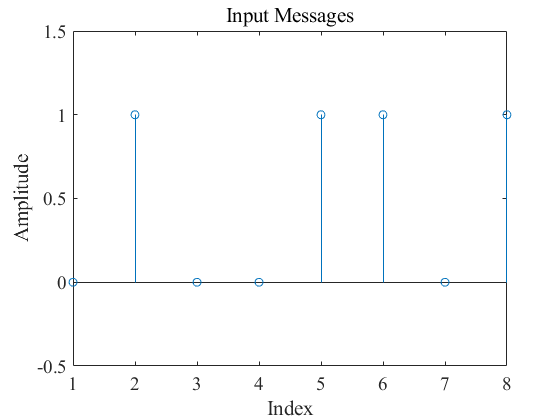

messages = [0 1 0 0 1 1 0 1];

stem(messages)
ylim([-0.5 1.5])
title('Input Messages')
xlabel('Index')
ylabel('Amplitude');

## 変調シンボル列の確認

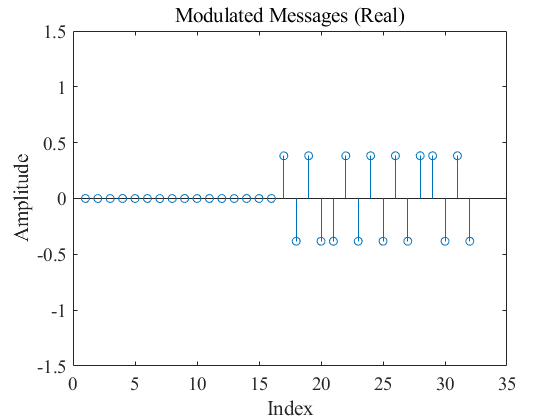

infoBinaryTilde = reshape(messages, [bitsPerSymbol,round(length(messages)/bitsPerSymbol)]);
infoBinary = infoBinaryTilde';
infoDecimal = bi2de(infoBinary, 'left-msb');

selectMatrixWH = zeros(length(infoDecimal), nHadamard);
theta = zeros(1, size(infoDecimal,1));
for k = 1:length(infoDecimal)
    selectMatrixWH(k,:) = matrixWH(infoDecimal(k)+1,:);
    theta(k) = infoDecimal(k)*((2*pi)/nHadamard);
end

infoModulatedTilde1 = zeros(length(infoDecimal), nHadamard);
for k = 1:length(infoDecimal)
    infoModulatedTilde1(k,:) = selectMatrixWH(k,:)*exp(1i*theta(k));
end

infoModulateTilde2 = infoModulatedTilde1.';
infoModulated = infoModulateTilde2(:);

stem(real(infoModulated))
ylim([-1.5 1.5])
title('Modulated Messages (Real)')
xlabel('Index')
ylabel('Amplitude')

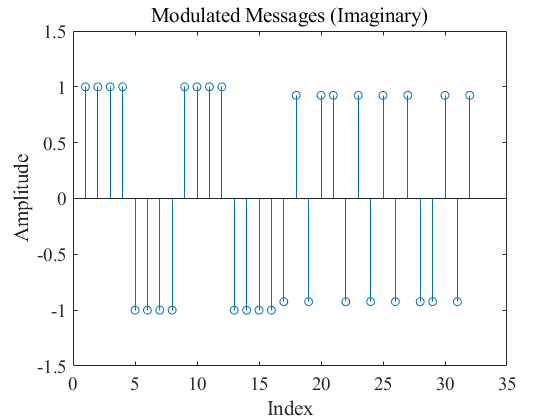

stem(imag(infoModulated))
ylim([-1.5 1.5])
title('Modulated Messages (Imaginary)')
xlabel('Index')
ylabel('Amplitude')

## DAC通過後の信号確認

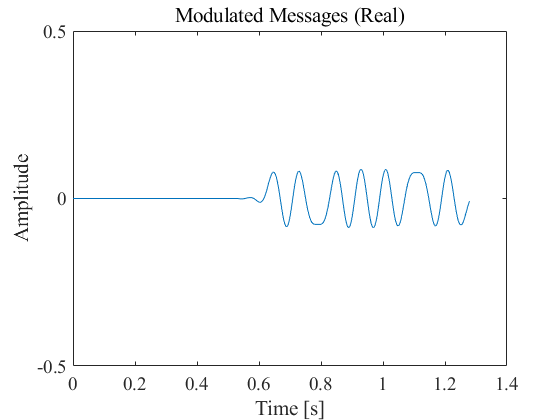

tt = 0:1/samplingFreq:length(infoModulated)*timePeriod-1/samplingFreq;

signalContinuousTilde = upfirdn(infoModulated.', filterDA, samplesPerSymbol);
signalContinuousTilde(1:filterDelay) = [];
signalContinuous = signalContinuousTilde(1:length(tt));

plot(tt, real(signalContinuous))
ylim([-0.5 0.5])
title('Modulated Messages (Real)')
xlabel('Time [s]')
ylabel('Amplitude')

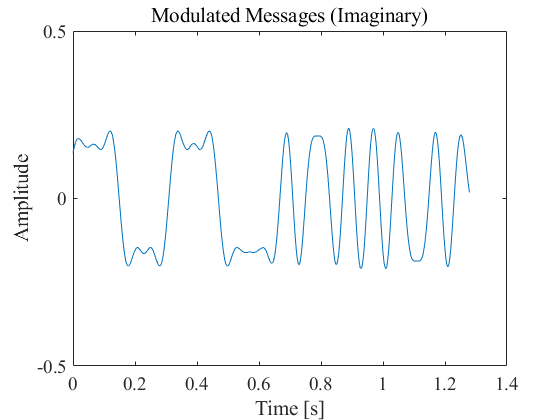

plot(tt, imag(signalContinuous))
ylim([-0.5 0.5])
title('Modulated Messages (Imaginary)')
xlabel('Time [s]')
ylabel('Amplitude')

## RFにアップコンバージョン後の信号確認

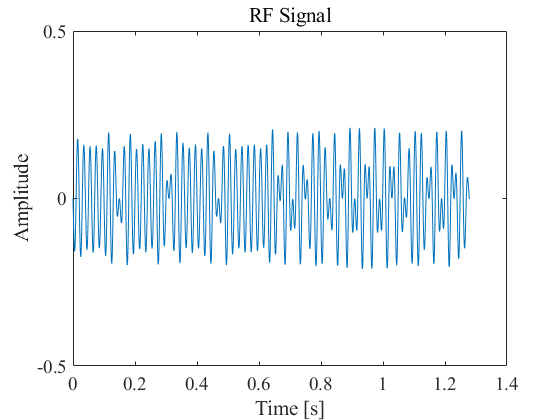

signalComplexRF = signalContinuous.*exp(1i*2*pi*CARRIER_FREQ*tt);

signalRF = real(signalComplexRF);

plot(tt, signalRF)
ylim([-0.5 0.5])
title('RF Signal')
xlabel('Time [s]')
ylabel('Amplitude')

## 雑音印加後の信号確認

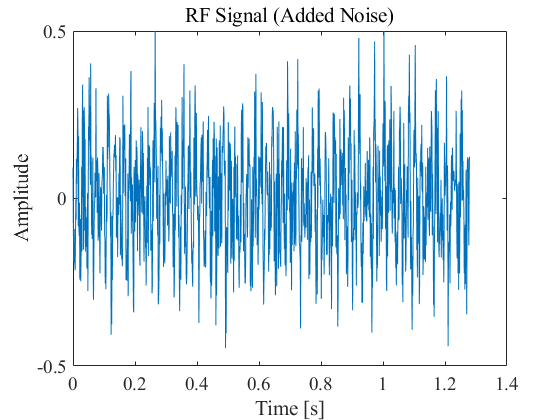

rng('shuffle')
signalAddedNoise = awgn(signalRF, snRatio, 'measured');  % signalAddedNoise = signalRF;

plot(tt, signalAddedNoise)
ylim([-0.5 0.5])
title('RF Signal (Added Noise)')
xlabel('Time [s]')
ylabel('Amplitude')

## 復調シンボル列の確認

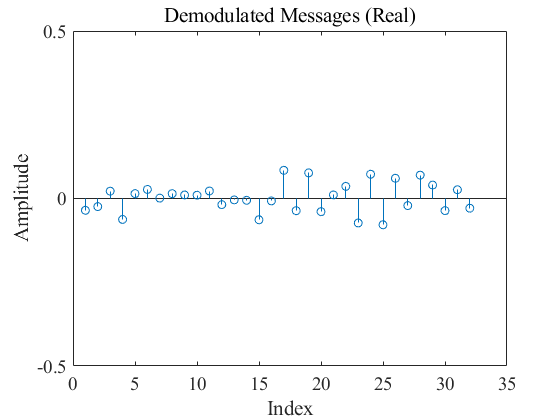

signalLPF = zeros(1, size(infoModulated,1));
for k = 1:length(infoModulated)
    signalLPF(k) = sum(signalAddedNoise(1+(k-1)*size(t,2):k*size(t,2)).*exp(-1i*2*pi*CARRIER_FREQ*t))*(2/(timePeriod*samplingFreq));
end

stem(real(signalLPF))
ylim([-0.5 0.5])
title('Demodulated Messages (Real)')
xlabel('Index')
ylabel('Amplitude')

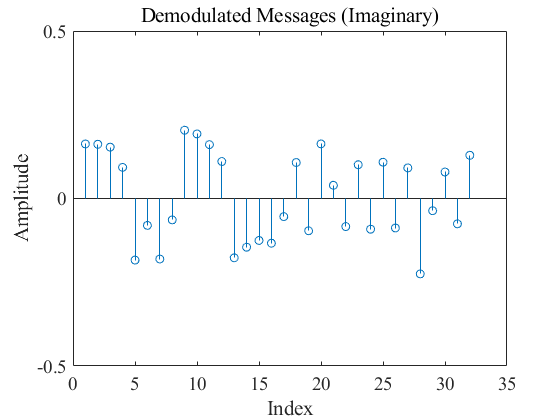

stem(imag(signalLPF))
ylim([-0.5 0.5])
title('Demodulated Messages (Imaginary)')
xlabel('Index')
ylabel('Amplitude')

## 出力ビット列の確認

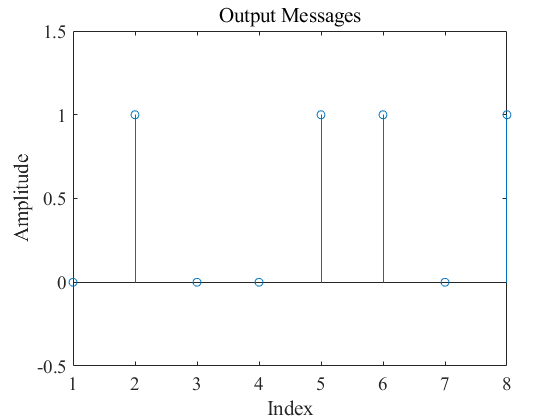

receivedInfoModulated = zeros(size(infoDecimal,1), nHadamard);
dacimalMax = zeros(size(infoDecimal,1), 1);
decimalIdx = zeros(size(infoDecimal,1), 1);
receivedInfoDecimal = zeros(size(infoDecimal,1), 1);
for k = 1:length(infoDecimal)
    receivedInfoModulated(k,:) = abs(signalLPF(1+(k-1)*nHadamard:k*nHadamard)*matrixWH.');
    [dacimalMax(k),decimalIdx(k)] = max(receivedInfoModulated(k,:));
    receivedInfoDecimal(k) = decimalIdx(k) - 1;
end

receivedInfoBinary = de2bi(receivedInfoDecimal, bitsPerSymbol, 'left-msb');
recievedMessagesTilde = receivedInfoBinary';
recievedMessages = recievedMessagesTilde(:)';

stem(recievedMessages)
ylim([-0.5 1.5])
title('Output Messages')
xlabel('Index')
ylabel('Amplitude')

## ビット誤り率の確認

bitErrorRate = biterr(messages, recievedMessages)/length(messages)

bitErrorRate = 0